% Kym Derriman (Partner: Evan Howell)
% Lab 6: Damped Harmonic Motion
% 10/17/2024

% -------------------------------------
% Spring Force vs Displacement Analysis
% -------------------------------------


% -----------------------------------------
% Import Measured Data weights = (0 - 100g)
% -----------------------------------------

% Preallocation and setup
num_measurements = 6;
position_means = zeros(1, num_measurements);
position_std_deviations = zeros(1, num_measurements);
position_std_err_mean = zeros(1, num_measurements);
filename.Temp = "S4L6_%d.txt";

% Loop to import and process data
for i = 1:num_measurements
    % Read data from corresponding file
    data = readtable(sprintf(filename.Temp, i));
    current_position = data.Position;
    N = length(current_position);
    position_means(i) = mean(current_position);
    position_std_deviations(i) = std(current_position);
    position_std_err_mean(i) = position_std_deviations(i)/sqrt(N);
end

% Convert position data to displacement by subtracting measured values of x - x_0. 
% I did this because I was getting a negative slope (negative B value, which was giving 
% me a complex number for my theoretical calculation of period in step 12.

% Extract x_0 from position means
x0 = position_means(1);

% Calculate and create displacement array
displacement_array = x0 - position_means;

% Mass of weights in kg (from stamps on weights)
mass_weights = [0.0, 0.1, 0.2, 0.3, 0.4, 0.5];

% -------------------------------
% Plot: Displacement vs. Mass
% -------------------------------

figure; grid on; box on;

% Plot Position with error bars
errorbar(mass_weights, displacement_array, position_std_err_mean, ...
    'ro', 'MarkerSize',5, 'DisplayName','Position vs Mass');

% Title and Labels with Uncertainties
title('Displacement vs Mass', 'FontSize', 14);
xlabel('Mass (kg)', 'FontSize', 11);
ylabel('Displacement (m)', 'FontSize', 11);
legend('Location','northwest');
set(gca, 'FontSize', 12);

% -----------------------------------
% Linear Fit for Spring Constant (k)
% -----------------------------------

% Performs a least-squares fit to the data, assuming a linear relationship between 
% the mass of the weights and the displacement according to Hooke's Law (F = -k*x)

% A = y-intercept of the fit, B = slope, related to spring constant k
% sigA and sigB are uncertainties in A, B weights = 1 / (std err mean)^2
[A, B, sigma_A, sigma_B] = linLSqFit_Derriman(mass_weights, ...
    displacement_array, 1 ./((position_std_err_mean).^2));

% Plot Linear Fit
figure; grid on; box on; hold on;

errorbar(mass_weights, displacement_array, position_std_err_mean, ...
    'ro', 'MarkerSize',5, 'DisplayName','Position vs Mass');

x_fit = linspace(min(mass_weights), max(mass_weights), 100);
y_fit = B * x_fit + A;
plot(x_fit, y_fit, 'k--', 'LineWidth', 1)
xlabel('Mass (kg)', 'FontSize', 11);
ylabel('Displacement (m)', 'FontSize', 11);

% Legend to show both the data and the fit
legend({'Displacement vs Mass', 'Linear Fit'}, 'Location', 'northwest');

% Set x-axis limits to only plot the data within the range
xlim([min(mass_weights), max(mass_weights)]);

hold off;

% -----------------------------------
% Calculation of Spring Constant (k)
% -----------------------------------

g = 9.81; % Acceleration due to gravity in m/s^2
k = g / B;
sig_k = (g * sigma_B) / (B^2);

fprintf('Parameters and Uncertainties y = Bx + A:\n');
fprintf('-------------------------------------------');
fprintf('Intercept (A) = %.4f ± %.4f m\n', A, sigma_A);
fprintf('Slope (B) = %.4f ± %.4f m/kg\n', B, sigma_B);
fprintf('Spring constant (k) = %.2f ± %.2f N/m\n', k, sig_k);
fprintf('-------------------------------------------');

% ----------------------------------------------
% Import and Prepare Measured Data weight = 500g
% ----------------------------------------------

% Data from oscillating spring with 500g weight attached.

tbl = readtable("L6_500g_Oscillation.txt");
times = tbl.Time;
positions = tbl.Position;
velocities = tbl.Velocity;
accelerations = tbl.Acceleration;

% Prepare data to plot oscillation about zero.

% Calculate the means 
position_means = mean(positions);
vel_means = mean(velocities);
accel_means = mean(accelerations);

% Shift plots down by subtracting means from measured values.
shifted_positions = positions - position_means;
shifted_velocities = velocities - vel_means;
shifted_accelerations = accelerations - accel_means;

% Convert position data to displacement data
x0 = shifted_positions(1);
displacements = x0 - shifted_positions;

% --------------------------------------------------
% Plot Displacement, Velocity, Acceleration Data
% --------------------------------------------------

figure;

% Subplot 1: Displacements (shifted)
subplot(3, 1, 1); plot(times, displacements);
title('Displacement vs Time*'); xlabel('Time (s)'); ylabel('Displacement (m)');

% Subplot 2: Velocities (shifted)
subplot(3, 1, 2); plot(times, shifted_velocities);
title('Velocity vs Time*'); xlabel('Time (s)'); ylabel('Velocity (m/s)');

% Subplot 3: Accelerations (shifted)
subplot(3, 1, 3); plot(times, shifted_accelerations);
title('Acceleration vs Time*'); xlabel('Time (s)'); ylabel('Acceleration (m/s^2)');

% Add annotation to indicate the asterisk explanation
annotation('textbox', [0.1, 0.01, 0.8, 0.05], 'String', ...
    '*Values shifted by means to oscillate about zero.','EdgeColor', 'none', ...
    'HorizontalAlignment', 'center', 'FontSize', 10);

% -----------------------------------------------------------------
% Find Zero-crossing Times for Displacement, Velocity, Acceleration
% -----------------------------------------------------------------

% Threshold values
trs_displacement = 0.0023;
trs_velocity = 0.015;
trs_accel = 0.05;

% Absolute value < trs implies zero-crossing
zero_cross_displ = times(abs(displacements) < trs_displacement);
zero_cross_veloc = times(abs(shifted_velocities) < trs_velocity);
zero_cross_accel = times(abs(shifted_accelerations) < trs_accel);

% Display the zero-crossing times
fprintf('Zero-Crossing Times for Displacement:\n');

Zero-Crossing Times for Displacement:


disp(zero_cross_displ');

    0.0333    0.4000    1.1000    2.1333    2.5000    3.2000    3.6000    4.3000    4.6666    5.3666    5.6999    6.3999    6.7666    7.4666    7.8666    8.5666    8.9332    9.6332    9.9666   10.6666   11.0332   11.7332   12.8332   13.8999   14.2332   14.9332   15.2998   15.9998   16.3665   17.0665   17.0998   17.4332   18.1665   18.4665   18.4998   19.1998   19.5331   20.2665   20.6331   21.3331   21.6998   22.3998   22.4331   22.7331   23.4664   23.7998   24.5331   24.8998   25.5997   25.9664   26.6664   26.9997   27.7331   28.0664   28.7997   29.1664   29.8664




fprintf('Zero-Crossing Times for Velocity:\n');

Zero-Crossing Times for Velocity:


disp(zero_cross_veloc');

    0.2000    0.7333    1.8000    2.3333    2.8666    3.4000    3.9333    4.4666    5.0000    5.5333    6.0666    6.5999    7.1333    7.6666    8.1999    8.7332    9.2666    9.2999    9.7999   10.3332   10.8666   11.3999   11.9332   12.4665   12.9999   13.5332   14.0665   14.5999   15.0998   15.6665   16.1998   16.7332   17.2665   17.7998   18.3331   18.8665   19.3665   19.8998   20.4331   20.9665   21.5331   22.0664   22.5664   23.0998   23.5998   23.6331   24.1664   24.6998   25.2331   26.2997   26.8331   27.3664   27.8664   28.4330   28.9664   29.4997




fprintf('Zero-Crossing Times for Acceleration:\n');

Zero-Crossing Times for Acceleration:


disp(zero_cross_accel');

    0.4667    1.0000    1.0333    1.0667    2.0666    2.6000    3.1333    4.2000    4.7333    5.2666    5.7666    6.3333    6.8666    8.4666    8.9999    9.5332   10.0666   10.5999   11.1332   11.6666   12.7332   13.7999   15.3998   15.8998   20.1665   23.3664   23.8998   24.4331   24.9997   25.4997   26.0331   27.6331   28.1664   28.6664   28.6997   29.7664   29.9664



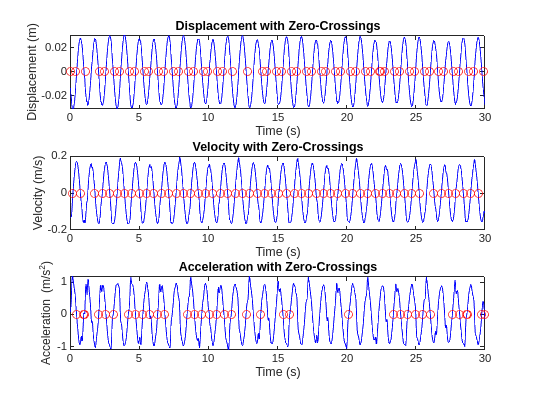


% Plot Displacement, Velocity, Acceleration with Zero-Crossings
figure;

% Subplot 1: Displacement with Zero-Crossings
subplot(3, 1, 1); 
plot(times, shifted_positions, 'b'); hold on;
plot(zero_cross_displ, zeros(size(zero_cross_displ)), 'ro');
title('Displacement with Zero-Crossings');
xlabel('Time (s)'); ylabel('Displacement (m)');

% Subplot 2: Velocity with Zero-Crossings
subplot(3, 1, 2); 
plot(times, shifted_velocities, 'b'); hold on;
plot(zero_cross_veloc, zeros(size(zero_cross_veloc)), 'ro');
title('Velocity with Zero-Crossings');
xlabel('Time (s)'); ylabel('Velocity (m/s)');

% Subplot 3: Acceleration with Zero-Crossings
subplot(3, 1, 3); 
plot(times, shifted_accelerations, 'b'); hold on;
plot(zero_cross_accel, zeros(size(zero_cross_accel)), 'ro');
title('Acceleration with Zero-Crossings');
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)');


% Display the zero-crossing times for closer inspection
disp('----------------------------------------------');

----------------------------------------------


disp('Zero-Crossing Times for Displacement, Velocity, and Acceleration:');

Zero-Crossing Times for Displacement, Velocity, and Acceleration:


disp('Displacement Zero-Crossing Times:');

Displacement Zero-Crossing Times:


disp(zero_cross_displ);

    0.0333
    0.4000
    1.1000
    2.1333
    2.5000
    3.2000
    3.6000
    4.3000
    4.6666
    5.3666
    5.6999
    6.3999
    6.7666
    7.4666
    7.8666
    8.5666
    8.9332
    9.6332
    9.9666
   10.6666
   11.0332
   11.7332
   12.8332
   13.8999
   14.2332
   14.9332
   15.2998
   15.9998
   16.3665
   17.0665
   17.0998
   17.4332
   18.1665
   18.4665
   18.4998
   19.1998
   19.5331
   20.2665
   20.6331
   21.3331
   21.6998
   22.3998
   22.4331
   22.7331
   23.4664
   23.7998
   24.5331
   24.8998
   25.5997
   25.9664
   26.6664
   26.9997
   27.7331
   28.0664
   28.7997
   29.1664
   29.8664



disp('Velocity Zero-Crossing Times:');

Velocity Zero-Crossing Times:


disp(zero_cross_veloc);

    0.2000
    0.7333
    1.8000
    2.3333
    2.8666
    3.4000
    3.9333
    4.4666
    5.0000
    5.5333
    6.0666
    6.5999
    7.1333
    7.6666
    8.1999
    8.7332
    9.2666
    9.2999
    9.7999
   10.3332
   10.8666
   11.3999
   11.9332
   12.4665
   12.9999
   13.5332
   14.0665
   14.5999
   15.0998
   15.6665
   16.1998
   16.7332
   17.2665
   17.7998
   18.3331
   18.8665
   19.3665
   19.8998
   20.4331
   20.9665
   21.5331
   22.0664
   22.5664
   23.0998
   23.5998
   23.6331
   24.1664
   24.6998
   25.2331
   26.2997
   26.8331
   27.3664
   27.8664
   28.4330
   28.9664
   29.4997



disp('Acceleration Zero-Crossing Times:');

Acceleration Zero-Crossing Times:


disp(zero_cross_accel);

    0.4667
    1.0000
    1.0333
    1.0667
    2.0666
    2.6000
    3.1333
    4.2000
    4.7333
    5.2666
    5.7666
    6.3333
    6.8666
    8.4666
    8.9999
    9.5332
   10.0666
   10.5999
   11.1332
   11.6666
   12.7332
   13.7999
   15.3998
   15.8998
   20.1665
   23.3664
   23.8998
   24.4331
   24.9997
   25.4997
   26.0331
   27.6331
   28.1664
   28.6664
   28.6997
   29.7664
   29.9664




% Set weights of 1/30 to zero-crossings in least-squares fit.
w_displacement = ones(length(zero_cross_displ), 1)*(1/30);
w_velocity = ones(length(zero_cross_veloc), 1)*(1/30);
w_acceleration = ones(length(zero_cross_accel), 1)*(1/30);

% Least-squares fit: A = y-intercept, B = time between zero-crossings
[A_disp, B_disp, sigma_A_disp, sigma_B_disp] = linLSqFit_Derriman( ...
    1:length(zero_cross_displ), zero_cross_displ, w_displacement);
[A_vel, B_vel, sigma_A_vel, sigma_B_vel] = linLSqFit_Derriman( ...
    1:length(zero_cross_veloc), zero_cross_veloc, w_velocity);
[A_accel, B_accel, sigma_A_accel, sigma_B_accel] = linLSqFit_Derriman( ...
    1:length(zero_cross_accel), zero_cross_accel, w_acceleration);


% --------------------------------------------------
% Extract T of Position, Velocity, and Acceleration
% --------------------------------------------------

% Extract value of T
T_displacement = 2 * B_disp; % Displacement
T_velocity = 2 * B_vel; % Velocity
T_acceleration = 2 * B_accel; % Acceleration

% Calculate uncertainties in T
sigma_T_disp = 2 * sigma_B_disp;
sigma_T_vel = 2 * sigma_B_vel;
sigma_T_accel = 2 * sigma_B_accel;

% To calculate theoretical value of T, we need the mass of the weight,
% the mass of the weight holder, and the effective mass of the spring.

% Mass of weight holder, weight, and spring (1/3 * spring mass), g to kg
mass_holder = 99.1/1000;
mass_weight = 500/1000;
mass_spring_eff = 29.2/1000;

% Total mass for theoretical T calculation
total_mass = mass_holder + mass_spring_eff + mass_weight;

% Calculate theoretical value of T with T = 2*pi*sqrt(m/k) where m is
% the mass of the weight, the weight holder and the spring weight.
T_theoretical = 2*pi*sqrt(total_mass/k);


% --------------------------------------------------
% Print Results for T Experimental vs T Theoretical
% --------------------------------------------------

% Data for periods and uncertainties
T_values = [T_displacement, T_velocity, T_acceleration];
sigma_T_values = [sigma_T_disp, sigma_T_vel, sigma_T_accel];
labels = {'Displacement', 'Velocity', 'Acceleration'};

% Loop through and print each result
for i = 1:length(T_values)
    fprintf('%s Data:\n', labels{i});
    fprintf('Measured period (T): %.4f s ± %.4f s\n', T_values(i), sigma_T_values(i));
end

Displacement Data:


Measured period (T): 1.0475 s ± 0.0882 s


Velocity Data:


Measured period (T): 1.0391 s ± 0.0906 s


Acceleration Data:


Measured period (T): 1.8387 s ± 0.1687 s


fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Theoretical period (T_theoretical): %.4f s\n', T_theoretical);

Theoretical period (T_theoretical): 1.0815 s


fprintf('--------------------------------------------------\n');

--------------------------------------------------


% --------------------------------------------------
% Calculate Phase Shift deltaPhi
% --------------------------------------------------

% Fitting coefficients A for displacement, velocity, and acceleration
A_displacement = A_disp; % From lsqFit for displacement
A_velocity = A_vel; % From lsqFit for velocity
A_acceleration = A_accel; % From lsqFit for acceleration

% Mean period of the system (T)
T_arr = [T_displacement, T_velocity, T_acceleration];
T = mean(T_arr);

% Time differences (deltaT) between displacement, velocity, and acceleration
delta_T1 = A_displacement - A_velocity;
delta_T2 = A_velocity - A_acceleration;

% Print delta_T values for inspection
fprintf('delta_T1 (displacement-velocity): %.4f s\n', delta_T1);

delta_T1 (displacement-velocity): 0.0650 s


fprintf('delta_T2 (velocity-acceleration): %.4f s\n', delta_T2);

delta_T2 (velocity-acceleration): 3.7242 s



% Calculate phase shifts
delta_phi1 = 2 * pi * (delta_T1 / T); % Between displacement and velocity
delta_phi2 = 2 * pi * (delta_T2 / T); % Between velocity and acceleration

% Display phase shift results
fprintf('Phase shift between displacement and velocity: %.4f radians\n', delta_phi1);

Phase shift between displacement and velocity: 0.3119 radians


fprintf('Phase shift between velocity and acceleration: %.4f radians\n', delta_phi2);

Phase shift between velocity and acceleration: 17.8837 radians


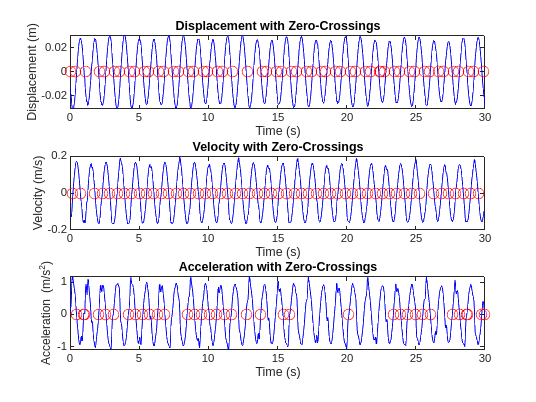

% Troubleshooting phase shift
figure;

% Subplot 1: Displacement with Zero-Crossings
subplot(3, 1, 1); 
plot(times, shifted_positions, 'b'); hold on;
plot(zero_cross_displ, zeros(size(zero_cross_displ)), 'ro', 'MarkerSize', 8);
title('Displacement with Zero-Crossings');
xlabel('Time (s)'); ylabel('Displacement (m)');

% Subplot 2: Velocity with Zero-Crossings
subplot(3, 1, 2); 
plot(times, shifted_velocities, 'b'); hold on;
plot(zero_cross_veloc, zeros(size(zero_cross_veloc)), 'ro', 'MarkerSize', 8);
title('Velocity with Zero-Crossings');
xlabel('Time (s)'); ylabel('Velocity (m/s)');

% Subplot 3: Acceleration with Zero-Crossings
subplot(3, 1, 3); 
plot(times, shifted_accelerations, 'b'); hold on;
plot(zero_cross_accel, zeros(size(zero_cross_accel)), 'ro', 'MarkerSize', 8);
title('Acceleration with Zero-Crossings');
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)');